# Data Analysis Project

Name: 

ID: 

In this project, you will be producing a data analysis report.  To do so, you will need to explore the dataset using a variety of data analysis methods.  Not every distribution and technique is appropriate to every dataset and you will need to make those judgements on an individual basis, though there are several things you should do as part of the project:

- produce a thorough examination of the distributions and scale parameters (e.g. mean and standard deviation)

- explore for correlations between data vectors (basic plots and correlation coefficients) and produce a regression model if applicable

- hypothesis testing an aspect of the data; the testing should have some point you would like to make (e.g., whether a region or data group varies from the global mean)

- use a multidimensional analysis technique to examine similarities/differences between data groups (e.g., rock type, species)

Not every analysis will provide an interesting or useful result, but should be look at as an exploration of the data.  You should also give a narrative discussing key observations about your analyses, though an interpretation is not necessary.  You will need to interpret the plots and/or results of your analysis in the context of what knowledge is gained through each.  

You DO NOT need to interpret the results in terms of a scientific process.  For example, if you found a linear relationship between elevation and crustal thickness, you may discuss the significance, but you do not need to discuss the relevance of the relationship to the principles of isostasy.

There are two datasets to choose from:

- Evaristo&McDonnell2017_vegetation&groundwater.xlsx - [https://doi.org/10.1038/srep44110](https://doi.org/10.1038/srep44110) A global database of vegetation type and groundwater observations.

- Kelson_etal2020.xlsx - [https://doi.org/10.1016/j.quascirev.2020.106259](https://doi.org/10.1016/j.quascirev.2020.106259) A global database of soil and surface isotopes.

A reference for each dataset is also provided in case you have questions about what some of the column abbreviations may be or what the data represent.  You will likely find some analyses in these references and it is acceptable to reproduce some of the same analyses, though you should also produce some new/different ones.

Each of these files can be loaded using readtable.m, though some modifications were made so that it could be easily read.  As some of these files have multiple tabs, the only tab that is loaded is the first tab unless otherwise specified.  In each case, the tab with the relevant data should be the first one.  Sometimes MATLAB will change the names of the columns when it imports the data.  You can see what the column names are at any time (assuming your table is named data) by typing data.Properties.VariableName (capital letters are important).  If you have difficulty loading the data let me know.

I look foward to your analyses. 

## Analysis

For the final project, I choose "vegetation and groundwater" dataset to analyze 

addpath 'Final project'\code\;
addpath 'Final project'\data\;
data=readtable("vegetation&groundwater.xlsx")

data = 531×28 table
    PAPERYEAR             JOURNALNAME                                                                           PAPERTITLE                                                                    COUNTRY                SITE                LAT       LONG                        ECOREGION                       ISOSYSTEM       PlantGenus               PlantSpecies                 Seed         NCBITaxonomyID    EVENTS    N     Mean    RootD95_m_    RootZoneStorage_mm_    DWT_m_    PET     MAP     RUNOFF_mmY_1_     AET      ARIDITY_INDEX              EXTRACTMETHOD

size(data)

ans =    531    28


**1) Produce a thorough examination of the distributions and scale parameters (e.g. mean and standard deviation)**

- **Distribution of locations:**

% distribution of locations
number_long = data.LONG;
number_lat = data.LAT;

mean_long = mean(number_long) % calculate mean of longitudes 

mean_long = -21.9932

long_std = std(number_long)  % calculate standard deviation of longitudes

long_std = 94.8490

long_skew = skewness(number_long) % calculate skewness of longitudes 

long_skew = 0.5345

mean_lat=mean(number_lat)

mean_lat = 21.8748

lat_std=std(number_lat)

lat_std = 24.9995

lat_skew=skewness(number_lat)

lat_skew = -1.1465

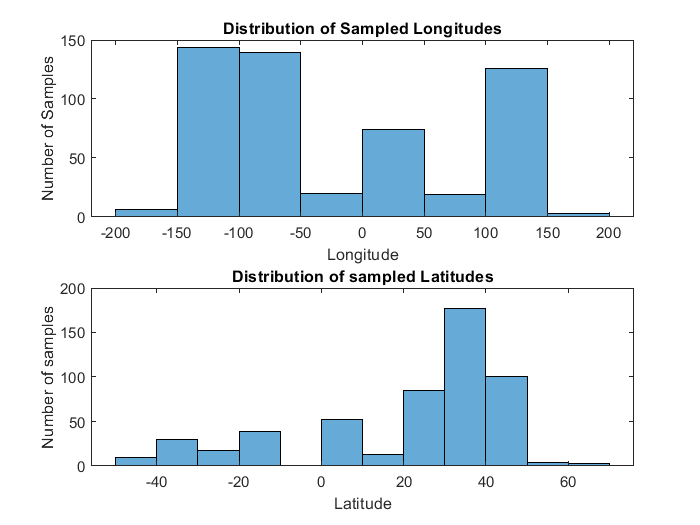

figure
subplot(2,1,1)
histogram(data.LONG)
ylabel('Number of Samples');
xlabel('Longitude');
title('Distribution of Sampled Longitudes');

subplot(2,1,2)
histogram(data.LAT)
ylabel('Number of samples');
xlabel('Latitude');
title('Distribution of sampled Latitudes');
histogram(data.LONG)
ylabel('Number of samples');
xlabel('Longitude');
title('Distribution of sampled Longitudes');

subplot(2,1,2)
histogram(data.LAT)
ylabel('Number of samples');
xlabel('Latitude');
title('Distribution of sampled Latitudes');

We can in the both Distribution of Longitudes and Latitudes histogram are not normally.

It is clear to see in the Longitude chart that those samples are mostly distributed in the West side rather than East side, and significant represented in the Northern hemisphere as looking at Latitude histogram.

As the skewness is 0.5345, the data are moderately skewed.

And this is the visualization of global distribution: 

figure
worldmap world

load coastlines
[latcells, loncells] = polysplit(coastlat, coastlon);

numel(latcells)

ans = 241

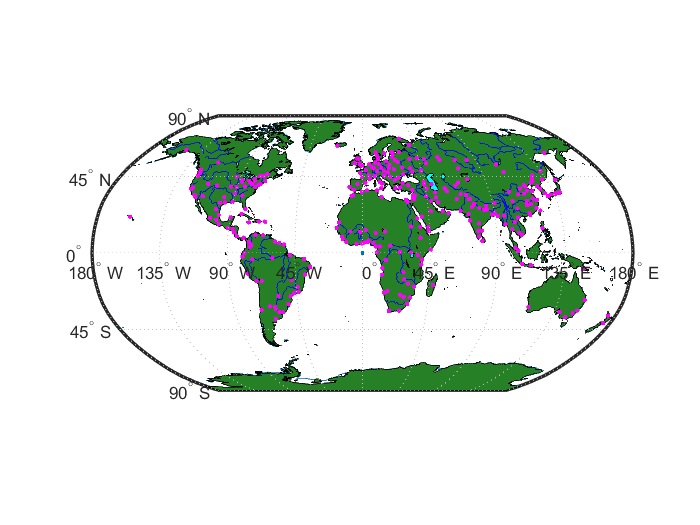

plotm(coastlat,coastlon)
geoshow('landareas.shp', 'FaceColor', [0.15 0.5 0.15])
geoshow('worldlakes.shp', 'FaceColor', 'cyan')
geoshow('worldrivers.shp', 'Color', 'blue')
geoshow('worldcities.shp', 'Marker', '.',...
                           'MarkerEdgeColor', 'magenta')
hold on
scatter(data.LONG,data.LAT,30,'.')
hold off

- **Distribution of plant species:**

plant_species = unique(data.PlantSpecies);
unique(data.PlantSpecies);
Plant_Species=categorical(data.PlantSpecies);
summary(Plant_Species)

     Abies faxoniana                  2 
     Abies fraseri                    1 
     Acacia erioloba                  1 
     Acacia tortilis                  1 
     Acer grandidentatum              2 
     Acer negundo                     2 
     Acer saccharum                   2 
     Achillea millefolium             1 
     Alchornea latifolia              1 
     Alchornea trewioides             1 
     Alhagi sparsifolia               1 
     Allocasuarina verticillata       1 
     Alnus glutinosa                  1 
     Alnus jorullensis                1 
     Alseis blackiana                 1 
     Ambrosia acanthicarpa            1 
     Amorpha canescens                1 
     A

- **Distribution of plant genus:**

plant_genus = unique(data.PlantGenus);
unique(data.PlantGenus);
Plant_Genus=categorical(data.PlantGenus);
summary(Plant_Genus)

     Abies                 3 
     Acacia                2 
     Acer                  6 
     Achillea              1 
     Alchornea             2 
     Alhagi                1 
     Allocasuarina         1 
     Alnus                 2 
     Alseis                1 
     Ambrosia              1 
     Amorpha               1 
     Anacardium            2 
     Andropogon            1 
     Annona                1 
     Apocynum              1 
     Arbutus               3 
     Arctostaphylos        2 
     Argyrodendron         1 
     Artemisia            12 
     Astragalus            2 
     AtripIex              1 
     

From the summary, we can see the largest species are exampled is Pinus sylvestris (7), and the largest plant genus is Quercus (41)

- **Distribution of seed**

seeds = unique(data.Seed);
unique(data.Seed);
Seeds=categorical(data.Seed);
summary(Seeds)

     angiosperm      473 
     gymnosperm       58 


From the Seeds Summary, it is clear to see angiosperm is moslty presented.

**2) Explore for correlations between data vectors (basic plots and correlation coefficients) and produce a regression model if applicable**

Pearsons Correlation Coefficient:

numerical=data{:,{'LONG','LAT','Mean','DWT_m_','PET','MAP','AET',}};
Anumerical=rmmissing(numerical);
Pearson = corr(Anumerical)

Pearson =     1.0000   -0.7120    0.2409   -0.2505    0.3999    0.3309    0.3094
   -0.7120    1.0000   -0.0181    0.1857   -0.3171   -0.2597   -0.2853
    0.2409   -0.0181    1.0000   -0.0673    0.2302   -0.0753   -0.0031
   -0.2505    0.1857   -0.0673    1.0000    0.1183   -0.1927   -0.2329
    0.3999   -0.3171    0.2302    0.1183    1.0000    0.1595    0.2518
    0.3309   -0.2597   -0.0753   -0.1927    0.1595    1.0000    0.9115
    0.3094   -0.2853   -0.0031   -0.2329    0.2518    0.9115    1.0000


Key take-away points from this table are:

- The strongest correlation is between AET and MAP which is 0.9115

- Besides AET and MAP, it seems that the rest of relationships are weak.

These relationships are indicated below:

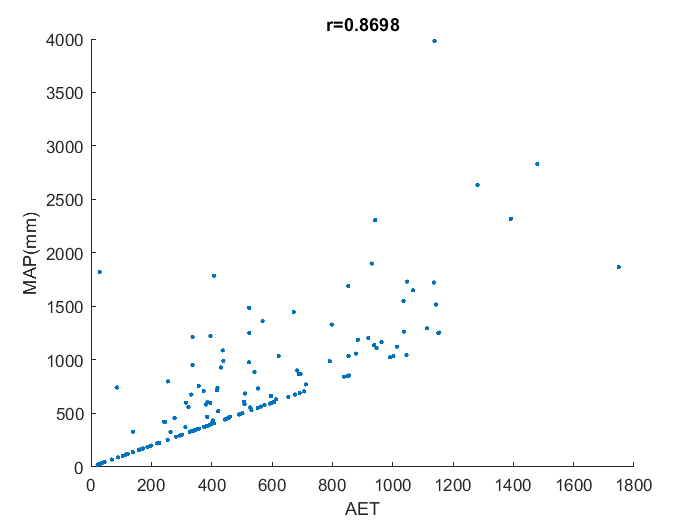

scatter(data.AET,data.MAP,'.')
title('r=0.8698')
xlabel('AET')
ylabel('MAP(mm)')

**3) Hypothesis testing an aspect of the data; the testing should have some point you would like to make (e.g., whether a region or data group varies from the global mean)**

**null hypothesis **= angiosperms and gynosperms have the different influence of groudwater

**alternate hypothesis** = angiosperms and gymnosperms have the same influence of groudwater

angiosperms = groupfilter(data,'Seed',@(x) all(x == "angiosperm"),'Seed')

angiosperms = 473×28 table
    PAPERYEAR             JOURNALNAME                                                                           PAPERTITLE                                                                    COUNTRY                SITE                LAT       LONG                        ECOREGION                       ISOSYSTEM       PlantGenus               PlantSpecies                 Seed         NCBITaxonomyID    EVENTS    N     Mean    RootD95_m_    RootZoneStorage_mm_    DWT_m_    PET     MAP     RUNOFF_mmY_1_     AET      ARIDITY_INDEX              EXTRACTMETHO

angio_mag=rmmissing(angiosperms.Mean); % mean of ground water contribute to angiosperms
angio_mean=mean(angio_mag)

angio_mean = 37.1003

gymnosperms = groupfilter(data,'Seed',@(x) all(x == "gymnosperm"),'Seed')

gymnosperms = 58×28 table
    PAPERYEAR                  JOURNALNAME                                                                                                     PAPERTITLE                                                                                         COUNTRY                  SITE                LAT       LONG                        ECOREGION                       ISOSYSTEM      PlantGenus             PlantSpecies                Seed         NCBITaxonomyID    EVENTS    N     Mean    RootD95_m_    RootZoneStorage_mm_    DWT_m_    PET     MAP     RUNOFF_mmY_1_     AET      ARIDITY

gymno_mag=rmmissing(gymnosperms.Mean); % mean of ground water contribute to gynosperms
gymno_mean=mean(gymno_mag)

gymno_mean = 27.9791

std_angio=std(angio_mag)

std_angio = 40.3380

std_gymno=std(gymno_mag)

std_gymno = 37.6278

We can see clearly that agiosperms have greater influence by groundwater (mean = 37.1003) then gymnosperms (mean = 27.9791)

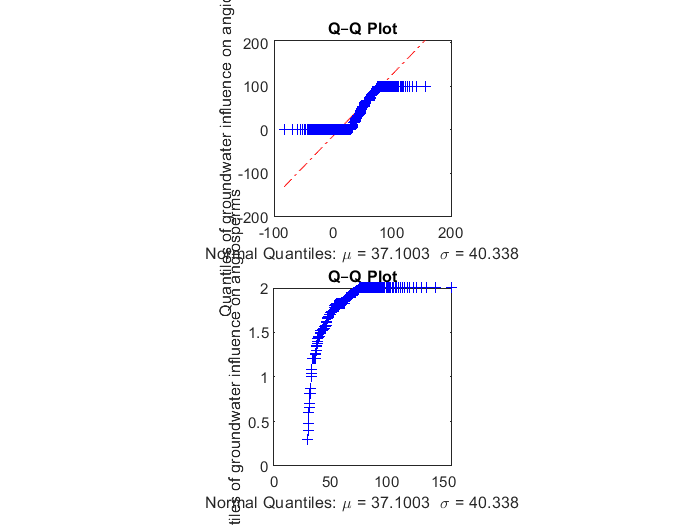

figure
subplot(2,1,1)
h = qqplot(angio_mag,makedist('Normal','mu',angio_mean,'sigma',std_angio));
title('Q–Q Plot')
ylabel('Quantiles of groundwater influence on angiosperms');
xlabel(['Normal Quantiles: \mu = ',num2str(angio_mean),'  \sigma = ',num2str(std_angio)]);
axis square;
set(gca,'Box','on');
subplot(2,1,2)
h = qqplot(log10(angio_mag),makedist('Normal','mu',angio_mean,'sigma',std_angio));
title('Q–Q Plot')
ylabel('Quantiles of groundwater influence on angiosperms');
xlabel(['Normal Quantiles: \mu = ',num2str(angio_mean),'  \sigma = ',num2str(std_angio)]);
axis square;
set(gca,'Box','on');

The first plot indicates the middle section is well represented by normal distribution, but the right above and left below show that it is not a well normal distribution.

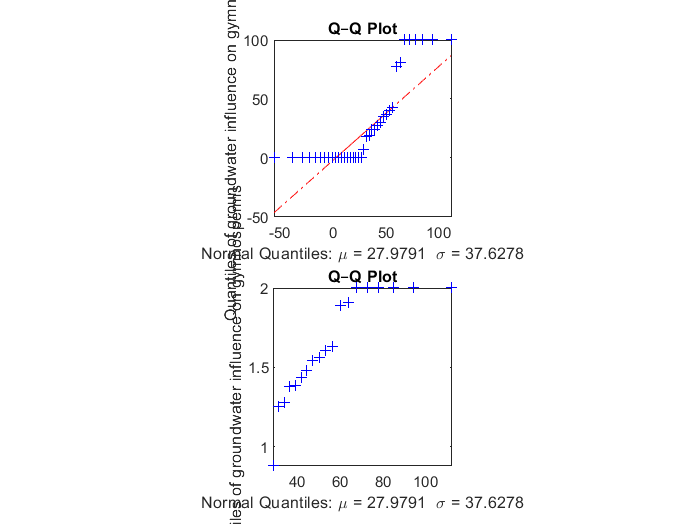

figure
subplot(2,1,1)
h = qqplot(gymno_mag,makedist('Normal','mu',gymno_mean,'sigma',std_gymno));
title('Q–Q Plot')
ylabel('Quantiles of groundwater influence on gymnosperms');
xlabel(['Normal Quantiles: \mu = ',num2str(gymno_mean),'  \sigma = ',num2str(std_gymno)]);
axis square;
set(gca,'Box','on');

subplot(2,1,2)
h = qqplot(log10(gymno_mag),makedist('Normal','mu',gymno_mean,'sigma',std_gymno));
title('Q–Q Plot')
ylabel('Quantiles of groundwater influence on gymnosperms');
xlabel(['Normal Quantiles: \mu = ',num2str(gymno_mean),'  \sigma = ',num2str(std_gymno)]);
axis square;
set(gca,'Box','on');

The first plot indicates the middle section is well represented by normal distribution but not better than angiosperms plot. Also, the right above and left below show that it is not a well normal distribution.

As has just been shown, the data for the most part fits normal distribution hence we can use the T test:

ttest2(angio_mag,gymno_mag)

ans = 0

T-test = 0 indicates a failure to reject the null hypothesis at the 5%.

It means that angiosperms and gynosperms have the different influence of groudwater

4) Use a multidimensional analysis technique to examine similarities/differences between data groups (e.g., rock type, species)

maxAngio=max(angiosperms.Mean)

maxAngio = 100

minAngio=min(angiosperms.Mean)

minAngio = 0

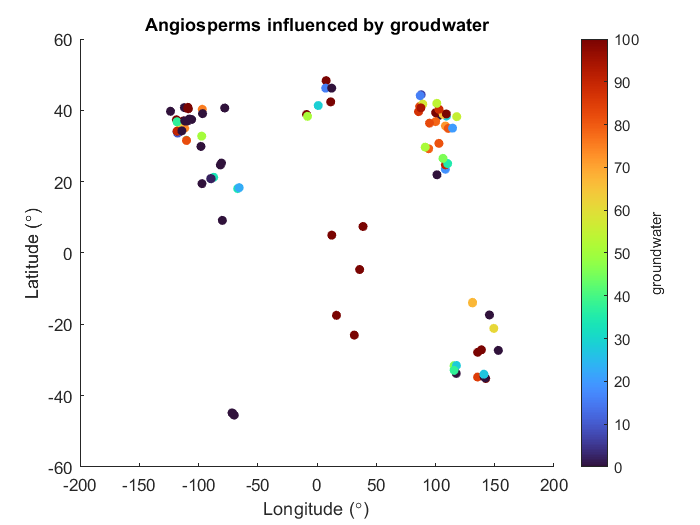

x = angiosperms.LONG;
y = angiosperms.LAT;
v = angiosperms.Mean;

figure
hold on;

scatter(x,y,30,v,'filled');
colormap("turbo");
cb = colorbar;
cb.Label.String = 'groundwater';
caxis([minAngio maxAngio]);
xlabel('Longitude (\circ)');
ylabel('Latitude (\circ)');
hold off;

title('Angiosperms influenced by groudwater');


maxGymno=max(gymnosperms.Mean)

maxGymno = 100

minGymno=min(gymnosperms.Mean)

minGymno = 0

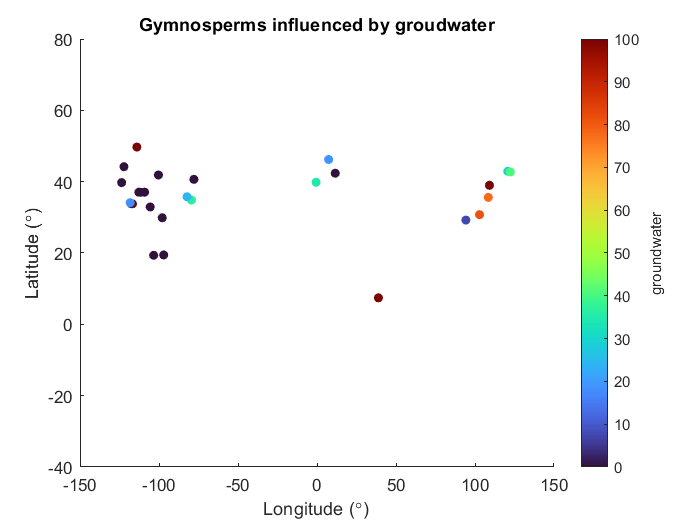

x = gymnosperms.LONG;
y = gymnosperms.LAT;
v = gymnosperms.Mean;

figure
hold on;

scatter(x,y,30,v,'filled');
colormap("turbo");
cb = colorbar;
cb.Label.String = 'groundwater';
caxis([minGymno maxGymno]);
xlabel('Longitude (\circ)');
ylabel('Latitude (\circ)');
hold off;

title('Gymnosperms influenced by groudwater');

These two map clearly presents three dimensions; latitude, longitude and groundwater influence on angiosperms and gymnosperms.